## Homework 3.2

clear all;
close all;
clc;

Given the equation $f(x) = e^{x^2} log(x+1) - 1$ consider the following three iterative methods. For each of them, verify the consistency of the schemes and apply them to compute root $\xi$ with $tol = 10^{-3}$.

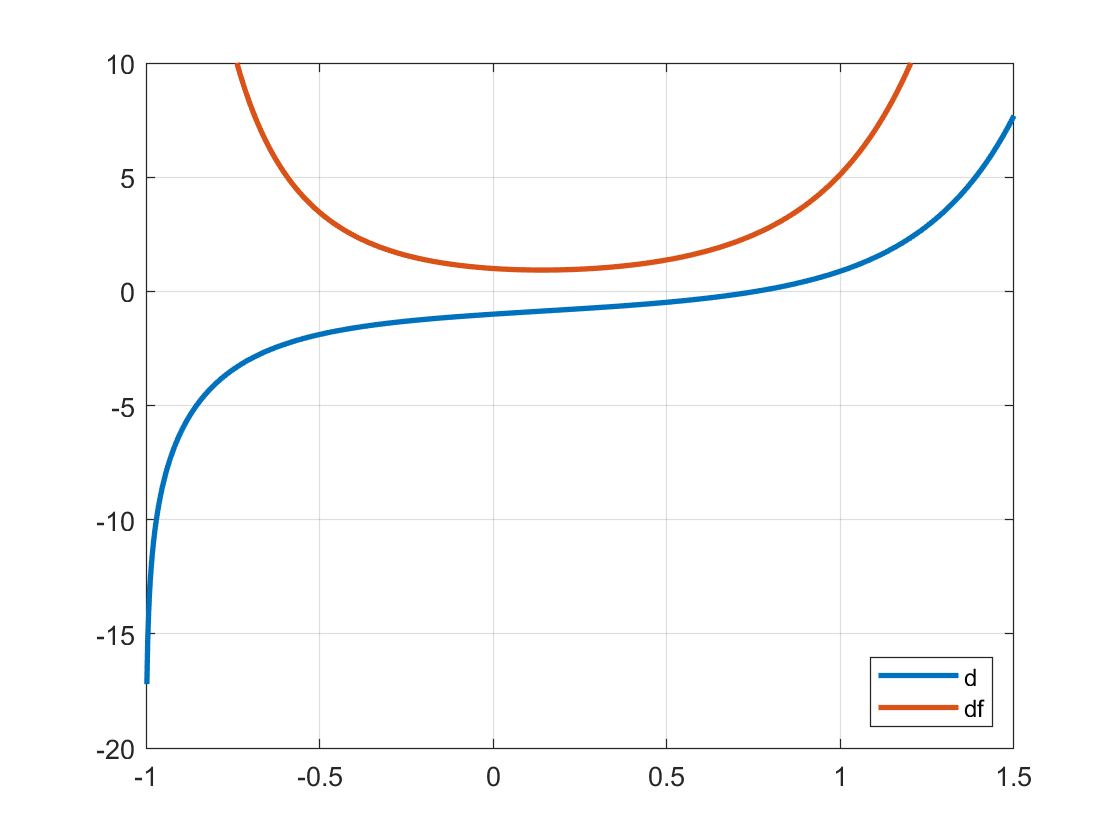

f = @(x) exp(x.^2).*log(x + 1) - 1;
df = @(x) (exp(x.^2).*(2*x.*(x+1).*log(x+1) + 1)) ./ (x+1);

x = linspace(-1, 1.5, 1000);

figure();
plot(x, f(x), 'LineWidth', 2);
hold on;
plot(x, df(x), 'LineWidth', 2);

grid on;
ylim([-20, 10]);
legend({'d', 'df'}, 'Location', 'southeast');

From the analytical analysis we know that the root $\xi \simeq 0.757137742...$

xi = 0.757137742;

### a. $x^{(k+1)} = \sqrt{-log(log(x^{(k)}+1))}$

Let's check the consistency:

phi = @(x) sqrt(-log(log(x + 1)));
phi(xi)

ans = 0.7571

$\phi(\xi) = \xi$ so the schema is **consistent**.

Let's compute $\xi$ by the fixed point method:

x0 = 0.5;
tol = 10e-3;
maxit = 10e6;

[xi, x_iter] = fixed_point(phi, x0, tol, maxit)

xi = 0.7604

x_iter =     0.5000    0.9501    0.6353    0.8424    0.7018    0.7948    0.7324    0.7738    0.7461    0.7645    0.7522    0.7604


### b. $x^{(k+1)} = x^{(k)} e^{(x^{(k)})^2} log(x^{(k)}+1)$

Let's check the consistency:

phi = @(x) x.*exp(x.^2).*log(x + 1);
phi(xi)

ans = 0.7668

$\phi(\xi) = 0.7668 \neq 0.7571 = \xi$ so it's not consistent. 

Let's try anyway to compute $\xi$ by the fixed point method:

x0 = 0.5;
tol = 10e-3;
maxit = 10e6;

[xi, x_iter] = fixed_point(phi, x0, tol, maxit)

xi = 1.6306e-05

x_iter =     0.5000    0.2603    0.0644    0.0040    0.0000


As we could expect, the fixed point method does not lead to the root $\xi$

Let's try to find the root $\xi$ with the **Newton method:**

[x, x_iter] = newton(f, df, x0, tol, maxit)

x = 0.7571

x_iter =     0.5000    0.8482    0.7679    0.7573    0.7571


We note that, with a starting point $x_0$ sufficently near to $\xi$ we are able to compure root $\xi$ in only 5 steps.

### Functions

Fixed point method

function [xi, x_iter] = fixed_point(phi, x0, tol, maxit)

  x_iter(1) = x0;

  for iter = 1:maxit

    x_iter(iter+1) = phi(x_iter(iter));

    if (abs (x_iter(iter+1) - x_iter(iter)) < tol)
      break;
    end

  end
  
  xi = x_iter(end);

end

Newton method

function [x, x_iter] = newton(f, df, x0, tol, Nmax)
    % Nmax since we don't know a priori if with the passed
    % tol we will reach a convergence

    x_iter(1) = x0;
    
    for k = 2:Nmax
        
        % Check if the derivative is zero or simil-zero
        if abs(df(x_iter(k-1))) < 1e-8
            break;
        end
        
        x_iter(k) = x_iter(k-1) - (f(x_iter(k-1)) / df(x_iter(k-1)));
    
        if abs(x_iter(k) - x_iter(k-1)) < tol
            break;
        end
    end
    
    x = x_iter(end);
end
